close all, clear all clc
% number of samples of each cluster
K = 100;
% offset of clusters
q = .6;
% define 2 groups of input data
A1 = [rand(1,K)-q; rand(1,K)+q]; B1 = [rand(1,K)+q; rand(1,K)+q]; C1 = [rand(1,K)+q; rand(1,K)-q]; D1 = [rand(1,K)-q; rand(1,K)-q]; A = [A1 C1];
B = [B1 D1];
% plot data
plot(A(1,:),A(2,:),'k+',B(1,:),B(2,:),'b*')
grid on
hold on

% coding (+1/0) for 2-class XOR problem (plots will be more interpretable with codes 0/1 instead of [0 1]/[1/0])
a = 0;
b = 1;

% define inputs (combine samples from all two classes)
P = [A B];
  
% define targets
T = [repmat(a,1,length(A)) repmat(b,1,length(B))];

% create a neural network
% Input, output and output layers sizes are set to 0. These sizes will automatically be
% configured to match particular data by train
net = feedforwardnet([20]); % We create a network with one hidden layer of 20 neurons (try
%also with [5 3])
% look at the default parameters % ... mse, purelin, ...
%
net

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 20
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inputConn

% train the neural network
[net,tr,Y,E] = train(net,P,T);
% Notice that tr has the indices of the training, validation and test data sets: % tr.trainInd
% tr.valInd
% tr.testInd
% show network
view(net)
% Accuracy
fprintf('Accuracy: %f\n',100-100*sum(abs((Y>0.5)-T))/length(T))

Accuracy: 100.000000


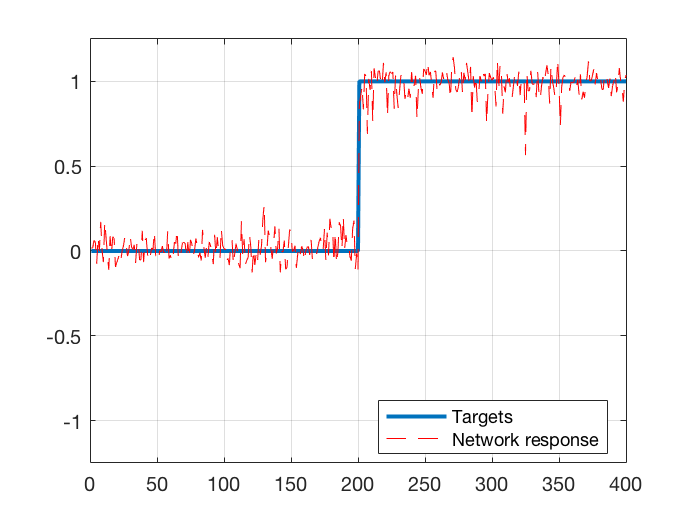


figure(2);
plot(T','linewidth',2);
hold on
plot(Y','r--');
grid on
legend('Targets','Network response','location','best');
ylim([-1.25 1.25]);

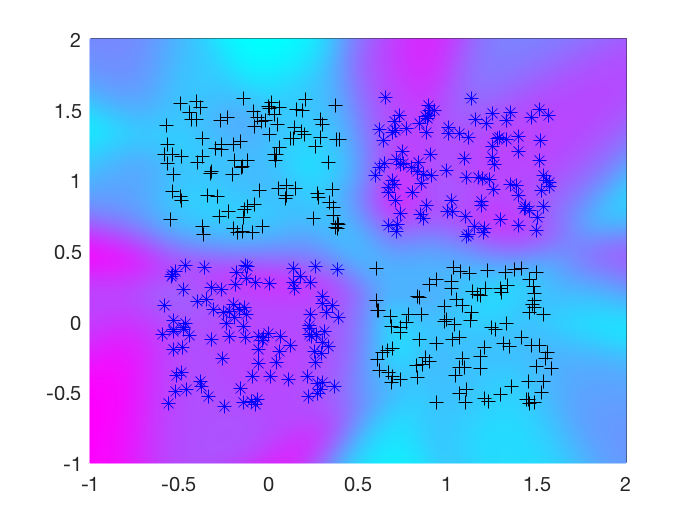



% generate a grid
span = -1:.005:2;
[P1,P2] = meshgrid(span,span);
pp = [P1(:) P2(:)]';
% simulate neural network on a grid
aa = net(pp);
% plot classification regions
figure(1)
mesh(P1,P2,reshape(aa,length(span),length(span))-5);
colormap cool
view(2)

% show network
view(net)